## **Driver test program to check Clothoids library**

**Test circle**

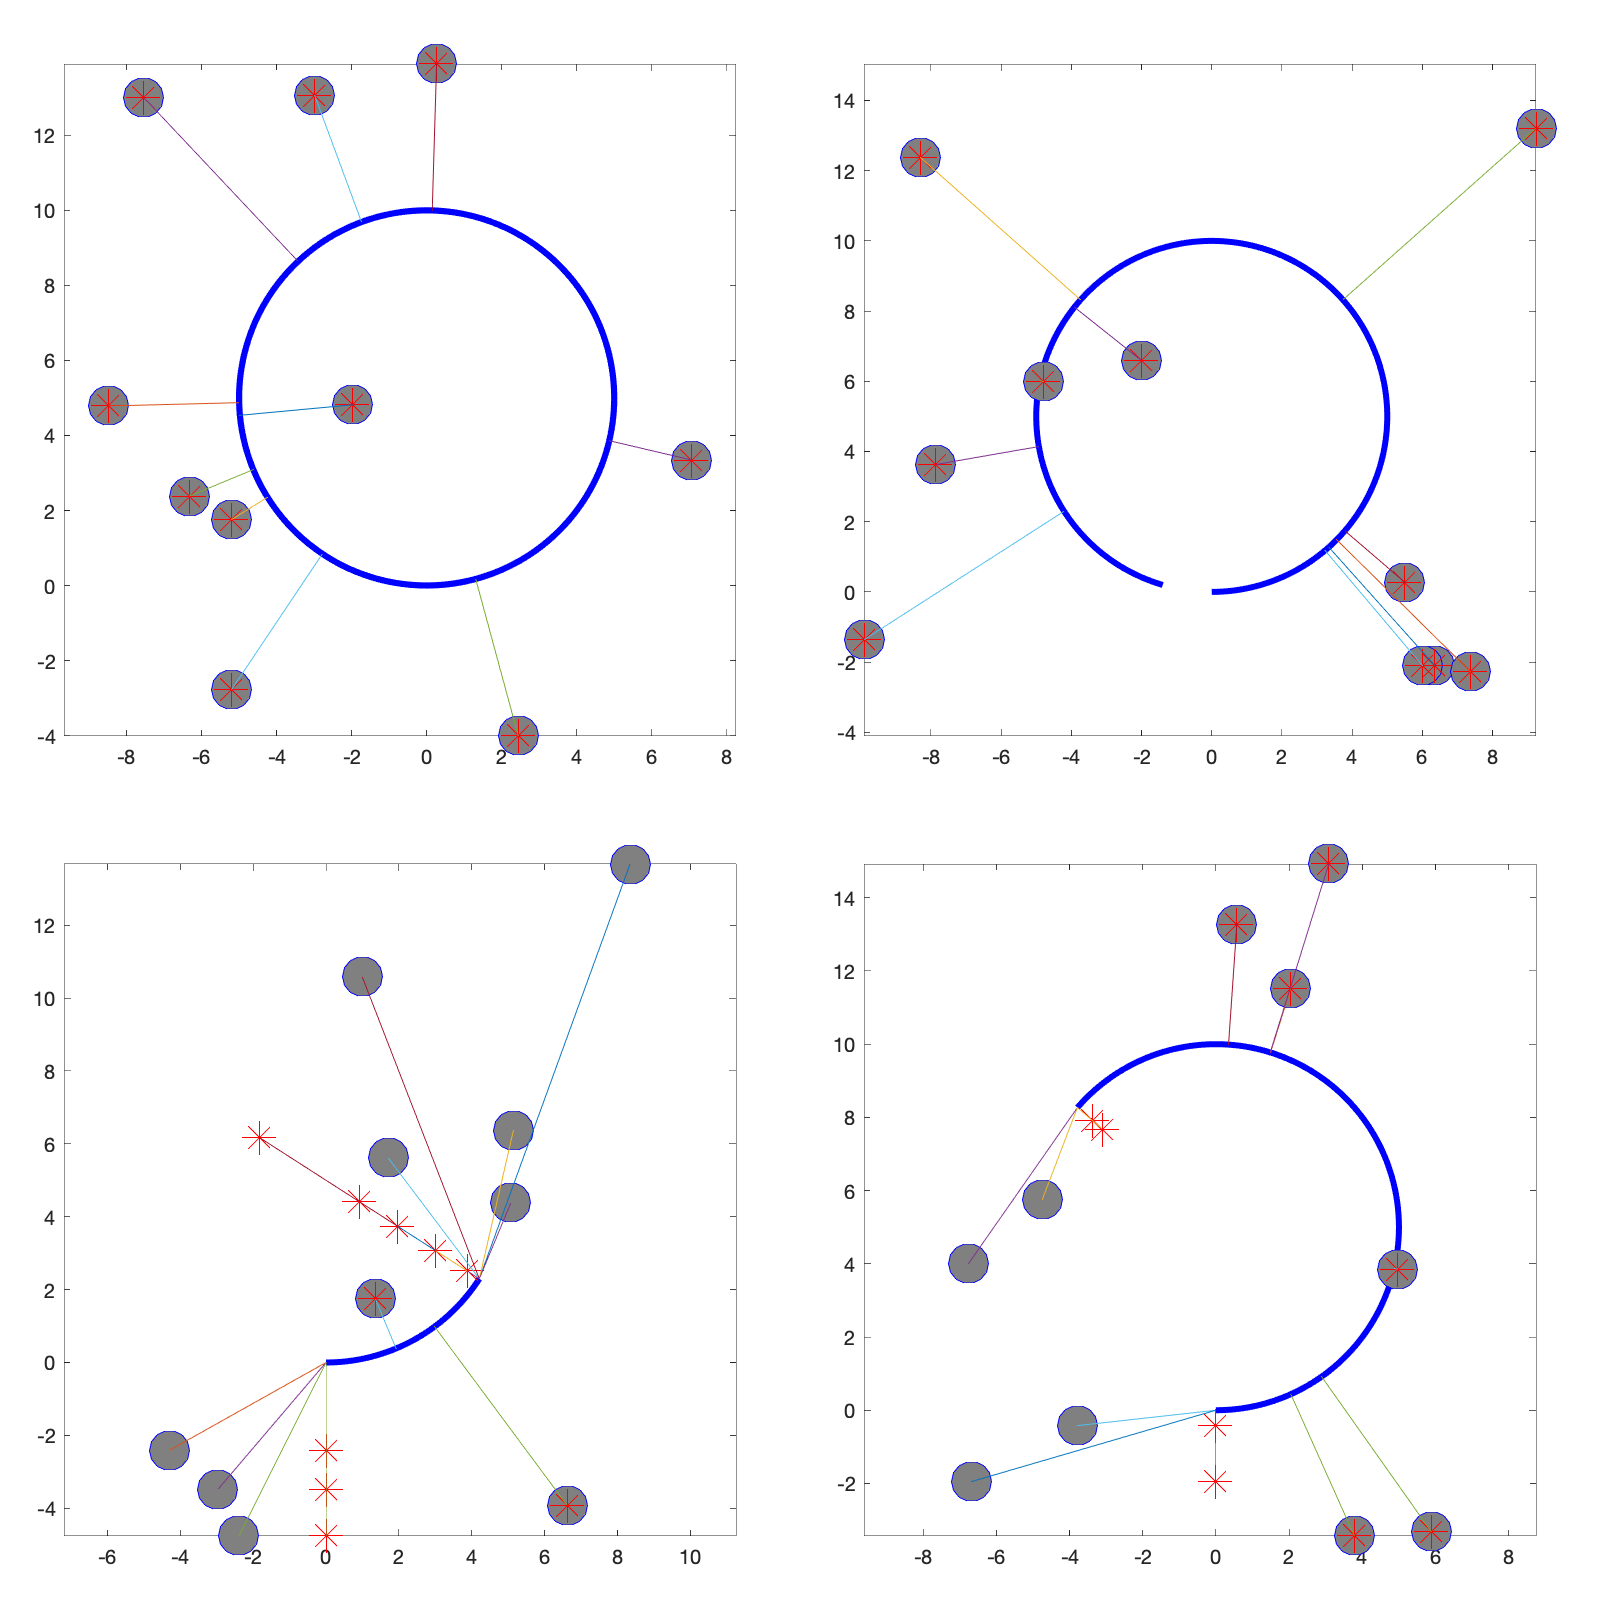

close all;

% check constructors
x0     = [0,0,0,0];
y0     = [0,0,0,0];
theta0 = 0;
kappa0 = [0.2, 0.2, 0.2, 0.2];
L      = [5,20,30,200];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end
  
  C = CircleArc( x0(kk), y0(kk), theta0, kappa0(kk), L(kk) );

  C.plot(400,{'Color','blue','LineWidth',3});
  
  N = 10;

  x         = (-10 + 20 * rand(N,1)).';
  y         = (-5  + 20 * rand(N,1)).';
  [s,t]     = C.find_coord(x,y);
  [xx,yy]   = C.eval(s,t);
  [xxx,yyy] = C.eval(s);

  hold on;  
  plot( x,   y, 'ro', 'MarkerSize',20,'MarkerEdgeColor','blue','MarkerFaceColor',[0.5,0.5,0.5]);
  plot( xx, yy, 'b*', 'MarkerSize',15,'MarkerEdgeColor','red','MarkerFaceColor',[0.9,0.9,0.5]);
  plot( [x;xxx;xx], [y;yyy;yy] );
  axis equal;
  %
end